clear all
clc
%set variables
Model.Nx=1600;                      % number of grid points in the x (row) direction
Model.Ny=1024;                       % number of grid points in the y (column) direction
Model.dx= 3.75e-05;                % grid point spacing in the x direction [m]
Model.dy= 3.75e-05;                % grid point spacing in the y direction [m]
Model.sample_rate_model=1e9/5;        %[HZ]
Model.sample_rate_exp=1e9/5;          %[HZ]
Model.amplitude=1;
Medium.speed_of_sound=1480;           %speed of sound in a homogeneous medium should be the same as the model[m/s]
absorption_coefficient=300;%[1/m]
Medium.sound_speed_sample=1490;%speed of sound inside the sample
Medium.density_sample=1040;%density of the sample
Geometry.l=0.019;                    %diameter of transducer
Geometry.sensor_thikness=3.75e-05; %thikness of the sensor
Geometry.distance=0.02439;%distance between the back of cuvette and transducer[m].
Geometry.cuvette_length=0.0055;%Width of the sample inside the cuvette
Geometry.cuvette_face=5e-3;   %thickness of PMMA layer
Geometry.cuvette_Gasket=0.5e-3   % thickness of silicon rubber

Geometry = struct with fields:
                  l: 0.0190
    sensor_thikness: 3.7500e-05
           distance: 0.0244
     cuvette_length: 0.0055
       cuvette_face: 0.0050
     cuvette_Gasket: 5.0000e-04


Geometry.cuvette_diameter=0.018; % diameter of the sample inside the cylindrical cuvette.[m]
a=1;


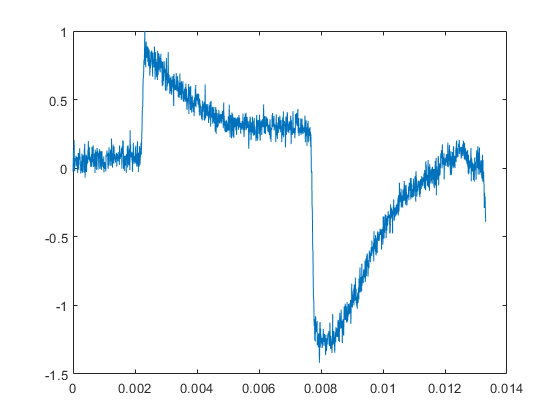

%read experimental data from TDMS files
filename = 'C:\Users\Marzieh\Documents\Marzieh\Data\18.07.2023\CUSO40.25M.18.7.2023_blue_ND0.6_test3_20230718_120943_276.tdms';
my_tdms_struct = TDMS_getStruct(filename,1);
channels=my_tdms_struct.M660D0;
S_exp=Mean_Tdms(channels);
figure(2000)
%S_exp=smoothdata(S_exp,'movmean',5);

plot(0:1/Model.sample_rate_exp*Medium.speed_of_sound:(length(S_exp)-1)*Medium.speed_of_sound/Model.sample_rate_exp,S_exp/max(S_exp(:)))

global S_model
global S_model_processed
global S_exp_processed
global S_exp

Running k-Wave simulation...
  start time: 29-Aug-2023 12:29:21
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 1.0435s
  starting time loop...
  estimated simulation time 1min 20.008s...
  GPU memory used: 1.8367 GB (of 11.9998 GB)
  simulation completed in 3min 28.5422s
  total computation time 3min 29.603s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0143    0.0148    0.0201    0.0062   -0.0156   -0.0192   -0.0222   -0.0018    0.0305    0.0799    0.1055    0.1018    0.0877    0.0786    0.0613    0.0568    0.0298    0.0115   -0.0404   -0.1092   -0.1462   -0.1656   -0.1485   -0.1234   -0.0658    0.0266    0.0675    0.0787    0.1115    0.0283   -0.0147   -0.0750   -0.1129   -0.0732   -0.0487    0.0196    0.0754    0.2008    0.2726    0.3231    0.2797    0.1578   -0.0193   -0.1317   -0.2335   -0.1838   -0.0909    0.0112    0.1488    0.2424


absorption_coefficient = 0.1500

a = 0.0100

RMSEcalculated = 19.7588

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          19.7588         
Running k-Wave simulation...
  start time: 29-Aug-2023 12:32:52
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.72911s
  starting time loop...
  estimated simulation time 1min 2.8063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 31.2269s
  total computation time 3min 31.973s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0106    0.0151    0.0189    0.0339    0.0358    0.0267    0.0258    0.0042   -0.0438   -0.0761   -0.0924   -0.0835   -0.0332    0.0139    0.0470    0.0627    0.0687    0.0554    0.0171   -0.0150   -0.0835   -0.1310   -0.1429   -0.1343   -0.1310   -0.0666    0.0010    0.0394    0.1032    0.2045    0.1708    0.1236    0.1097    0.1319    0.1950    0.1345    0.0600    0.0746    0.0826    0.0352   -0.0846   -0.1515   -0.2229   -0.1858   -0.1241   -0.0385    0.0513    0.1775    0.1777    0.1205


absorption_coefficient = 0.1718

a = 0.0100

RMSEcalculated = 25.7638

Running k-Wave simulation...
  start time: 29-Aug-2023 12:36:25
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.68574s
  starting time loop...
  estimated simulation time 1min 2.6063s...
  GPU memory used: 1.824 GB (of 11.9998 GB)
  simulation completed in 3min 33.2948s
  total computation time 3min 33.997s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0143    0.0148    0.0201    0.0062   -0.0156   -0.0192   -0.0222   -0.0018    0.0305    0.0799    0.1055    0.1018    0.0877    0.0786    0.0613    0.0568    0.0298    0.0115   -0.0404   -0.1092   -0.1462   -0.1656   -0.1485   -0.1234   -0.0658    0.0266    0.0675    0.0787    0.1115    0.0283   -0.0147   -0.0750   -0.1129   -0.0732   -0.0487    0.0196    0.0754    0.2008    0.2726    0.3231    0.2797    0.1578   -0.0193   -0.1317   -0.2335   -0.1838   -0.0909    0.0112    0.1488    0.2424


absorption_coefficient = 0.1500

a = 0.0122

RMSEcalculated = 17.7121

     1            3          17.7121         initial simplex
Running k-Wave simulation...
  start time: 29-Aug-2023 12:40:00
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.66649s
  starting time loop...
  estimated simulation time 1min 4.8065s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 33.5202s
  total computation time 3min 34.201s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0168    0.0092   -0.0032   -0.0177   -0.0134   -0.0034    0.0204    0.0496    0.0827    0.0787    0.0607    0.0304    0.0215    0.0001   -0.0146   -0.0127   -0.0176   -0.0293   -0.0228   -0.0235   -0.0237   -0.0620   -0.0671   -0.0319    0.0255    0.0635    0.0856    0.1159    0.1371    0.0795    0.0043    0.0001    0.0757    0.1313    0.2678    0.2892    0.3135    0.2657    0.0990   -0.0613   -0.1443   -0.1827   -0.1968   -0.1844   -0.2009   -0.0930    0.0076    0.1343    0.2029    0.2538


absorption_coefficient = 0.1304

a = 0.0122

RMSEcalculated = 22.1972

Running k-Wave simulation...
  start time: 29-Aug-2023 12:43:35
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.76381s
  starting time loop...
  estimated simulation time 1min 3.0063s...
  GPU memory used: 1.824 GB (of 11.9998 GB)
  simulation completed in 3min 31.6719s
  total computation time 3min 32.451s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0157    0.0169    0.0241    0.0286    0.0266    0.0168    0.0001   -0.0229   -0.0382   -0.0362   -0.0198    0.0090    0.0302    0.0399    0.0225   -0.0127   -0.0874   -0.1536   -0.1987   -0.2148   -0.1731   -0.0732    0.0483    0.1245    0.1866    0.2158    0.1990    0.1636    0.0258   -0.0618   -0.1262   -0.0976   -0.0457    0.0522    0.1878    0.2864    0.2581    0.1712    0.0440   -0.0711   -0.1719   -0.1960   -0.2219   -0.1476   -0.0651   -0.0161    0.0125    0.0672    0.0999    0.1458


absorption_coefficient = 0.1398

a = 0.0116

RMSEcalculated = 17.9047

     2            5          17.7121         contract outside
Running k-Wave simulation...
  start time: 29-Aug-2023 12:47:08
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.65153s
  starting time loop...
  estimated simulation time 1min 3.2063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 31.8166s
  total computation time 3min 32.484s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0157    0.0169    0.0242    0.0342    0.0465    0.0524    0.0345    0.0045   -0.0178   -0.0254   -0.0153    0.0175    0.0479    0.0797    0.0740    0.0527    0.0209   -0.0241   -0.0667   -0.1143   -0.1836   -0.1835   -0.1878   -0.1801   -0.1360   -0.0636    0.0485    0.1565    0.1880    0.1813    0.2839    0.2575    0.1985    0.1300    0.0801   -0.0612   -0.1173   -0.1740   -0.1538   -0.0234    0.0236    0.0545    0.0941    0.1805    0.1981    0.1045   -0.0346   -0.1033   -0.1835   -0.2545


absorption_coefficient = 0.1398

a = 0.0138

RMSEcalculated = 27.0258

Running k-Wave simulation...
  start time: 29-Aug-2023 12:50:42
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.5908s
  starting time loop...
  estimated simulation time 1min 2.4062s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 31.9919s
  total computation time 3min 32.594s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0147    0.0136    0.0390    0.0608    0.0588    0.0635    0.0871    0.1076    0.1260    0.1272    0.1235    0.1033    0.0540    0.0057   -0.0363   -0.0739   -0.0743   -0.0507   -0.0330   -0.0126   -0.0183   -0.0300   -0.0345   -0.0804   -0.1363   -0.1242   -0.1498   -0.1267   -0.1348   -0.1220   -0.1023   -0.1059   -0.0945   -0.0862   -0.0584    0.0423    0.1776    0.2364    0.2422    0.2103    0.0935   -0.0845   -0.2152   -0.2351   -0.0985    0.0433    0.2109    0.3117    0.4052    0.4720


absorption_coefficient = 0.1474

a = 0.0109

RMSEcalculated = 16.0572

     3            7          16.0572         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 12:54:15
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.60949s
  starting time loop...
  estimated simulation time 1min 2.2062s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.0711s
  total computation time 3min 32.694s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0149    0.0259    0.0305    0.0096    0.0056    0.0209    0.0340    0.0595    0.0731    0.0796    0.0708    0.0491    0.0191   -0.0055   -0.0041   -0.0124   -0.0105   -0.0130    0.0015   -0.0137   -0.0218    0.0010   -0.0084    0.0088    0.0198    0.0111   -0.0394   -0.0161   -0.0196    0.0318    0.0758    0.1221    0.1783    0.2274    0.1705    0.2230    0.1699    0.0854    0.0647   -0.0658   -0.2047   -0.3232   -0.3067   -0.2699   -0.1682   -0.0216    0.1137    0.2469    0.2771


absorption_coefficient = 0.1580

a = 0.0115

RMSEcalculated = 15.6024

Running k-Wave simulation...
  start time: 29-Aug-2023 12:57:49
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.635s
  starting time loop...
  estimated simulation time 1min 2.6063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.0696s
  total computation time 3min 32.72s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0114    0.0155    0.0315    0.0442    0.0592    0.0516    0.0286   -0.0031   -0.0294   -0.0580   -0.0716   -0.0712   -0.0554   -0.0396   -0.0075    0.0171    0.0449    0.0225   -0.0017   -0.0188   -0.0171    0.0064    0.0623    0.1237    0.1702    0.2106    0.2367    0.2339    0.2180    0.1795    0.1419    0.1837    0.1680    0.0672    0.0671    0.0623    0.0322    0.0009    0.0520    0.0432   -0.0330   -0.0808   -0.1336   -0.2147   -0.2120   -0.1831   -0.0412    0.0412    0.1794    0.2136


absorption_coefficient = 0.1676

a = 0.0114

RMSEcalculated = 16.3195

     4            9          15.6024         reflect
Running k-Wave simulation...
  start time: 29-Aug-2023 13:01:23
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.61622s
  starting time loop...
  estimated simulation time 1min 2.4062s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.0675s
  total computation time 3min 32.7s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0135    0.0076    0.0112    0.0232    0.0220    0.0264    0.0316    0.0438    0.0512    0.0452    0.0417    0.0514    0.0392    0.0229    0.0105   -0.0006    0.0074   -0.0121   -0.0165   -0.0274   -0.0804   -0.1072   -0.1338   -0.1388   -0.1240   -0.0957   -0.0549   -0.0406   -0.0249   -0.0263   -0.0384   -0.0480    0.0410    0.0629    0.0885    0.0800    0.0348    0.0542    0.0966    0.1097    0.1212    0.0477   -0.0577   -0.1562   -0.1501   -0.1532   -0.0485    0.0351    0.1308    0.2474


absorption_coefficient = 0.1553

a = 0.0103

RMSEcalculated = 19.0093

Running k-Wave simulation...
  start time: 29-Aug-2023 13:04:56
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.6412s
  starting time loop...
  estimated simulation time 1min 4.0064s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.1528s
  total computation time 3min 32.809s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0141    0.0115   -0.0171   -0.0173   -0.0063    0.0178    0.0392    0.0523    0.0532    0.0441    0.0395    0.0340    0.0426    0.0475    0.0277    0.0059    0.0266    0.0349    0.0110   -0.0279   -0.0674   -0.0979   -0.0884   -0.0646   -0.0712   -0.0734   -0.1054   -0.1419   -0.1889   -0.1662   -0.1357   -0.0423    0.0440    0.1434    0.2287    0.3557    0.4066    0.3347    0.2361    0.1811    0.0511    0.0186   -0.0360   -0.0029    0.0349    0.0348    0.0652    0.1106    0.0644    0.0220


absorption_coefficient = 0.1513

a = 0.0117

RMSEcalculated = 16.2097

     5           11          15.6024         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 13:08:30
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.62974s
  starting time loop...
  estimated simulation time 1min 4.2064s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.1785s
  total computation time 3min 32.821s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0137    0.0111    0.0134    0.0125    0.0355    0.0598    0.0677    0.0625    0.0703    0.0612    0.0530    0.0611    0.0614    0.0599    0.0297    0.0000   -0.0472   -0.1166   -0.1558   -0.1740   -0.1391   -0.0726    0.0238    0.1001    0.1086    0.0630    0.0320   -0.0843   -0.2389   -0.3186   -0.2763   -0.1752    0.0417    0.2781    0.4781    0.5965    0.5088    0.3697    0.2580    0.0501   -0.1036   -0.1846   -0.1884   -0.0986    0.0169    0.1615    0.2256    0.1670    0.0352   -0.0763


absorption_coefficient = 0.1540

a = 0.0107

RMSEcalculated = 16.6248

Running k-Wave simulation...
  start time: 29-Aug-2023 13:12:03
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.61744s
  starting time loop...
  estimated simulation time 1min 2.8063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.1114s
  total computation time 3min 32.744s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0140    0.0165    0.0111   -0.0119   -0.0134   -0.0037    0.0123    0.0096    0.0239    0.0242    0.0327    0.0463    0.0546    0.0605    0.0791    0.0735    0.0691    0.0737    0.0542    0.0790    0.1181    0.1039    0.0550    0.0019   -0.0199   -0.0606   -0.1217   -0.1542   -0.1517   -0.1711   -0.1321   -0.1408   -0.0225    0.0741    0.1520    0.2175    0.2341    0.3190    0.3219    0.2695    0.2505    0.2256    0.1137    0.0220   -0.0083   -0.0191   -0.0747   -0.0877   -0.0576   -0.0072


absorption_coefficient = 0.1520

a = 0.0115

RMSEcalculated = 15.8110

     6           13          15.6024         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 13:15:37
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.60734s
  starting time loop...
  estimated simulation time 1min 4.8065s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.125s
  total computation time 3min 32.748s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0122    0.0131    0.0269    0.0538    0.0844    0.1048    0.0995    0.0682    0.0285    0.0053   -0.0121   -0.0295   -0.0329   -0.0256   -0.0102    0.0170    0.0537    0.0798    0.0887    0.0841    0.0599    0.0024   -0.0540   -0.1051   -0.1279   -0.0993   -0.0350    0.0403    0.0976    0.1291    0.1435    0.0508    0.0288    0.0275   -0.0583   -0.1104   -0.0492    0.0426    0.0387   -0.0187    0.0250    0.0126   -0.0741   -0.1678   -0.1590   -0.0657    0.0462    0.2212    0.2923    0.2792


absorption_coefficient = 0.1628

a = 0.0120

RMSEcalculated = 15.9016

Running k-Wave simulation...
  start time: 29-Aug-2023 13:19:11
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.61736s
  starting time loop...
  estimated simulation time 1min 3.0063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 31.9544s
  total computation time 3min 32.588s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0210    0.0208   -0.0039   -0.0112   -0.0095    0.0041    0.0198    0.0424    0.0529    0.0689    0.0826    0.0835    0.0742    0.0492    0.0085   -0.0180   -0.0525   -0.0851   -0.1002   -0.0747   -0.0263    0.0295    0.0550    0.0684    0.0656    0.0308   -0.0659   -0.1312   -0.1574   -0.2148   -0.1497   -0.0727    0.0394    0.1199    0.1599    0.1867    0.1714    0.1572    0.2020    0.2208    0.2430    0.2911    0.2442    0.1383    0.0003   -0.0750   -0.1489   -0.1822   -0.1270


absorption_coefficient = 0.1589

a = 0.0117

RMSEcalculated = 15.7090

     7           15          15.6024         contract outside
Running k-Wave simulation...
  start time: 29-Aug-2023 13:22:44
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.62915s
  starting time loop...
  estimated simulation time 1min 3.4063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.0401s
  total computation time 3min 32.682s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0118    0.0085   -0.0169   -0.0117    0.0167    0.0540    0.0803    0.0981    0.0860    0.0575    0.0260   -0.0050   -0.0351   -0.0471   -0.0468   -0.0381   -0.0537   -0.0784   -0.1152   -0.1407   -0.1286   -0.0971   -0.0611   -0.0185    0.0365    0.0789    0.1217    0.1353    0.0879    0.0044   -0.0843   -0.1337   -0.0927   -0.0462    0.0120    0.0672    0.1114    0.1060   -0.0018   -0.1235   -0.2220   -0.3153   -0.3155   -0.2294   -0.1036    0.0885    0.2617    0.3901    0.4511    0.4346


absorption_coefficient = 0.1650

a = 0.0118

RMSEcalculated = 15.7357

Running k-Wave simulation...
  start time: 29-Aug-2023 13:26:18
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.61873s
  starting time loop...
  estimated simulation time 1min 2.6063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.1109s
  total computation time 3min 32.744s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0124    0.0169    0.0340    0.0180    0.0136   -0.0016    0.0095    0.0345    0.0810    0.1330    0.1707    0.1658    0.1273    0.0802    0.0200   -0.0476   -0.0826   -0.0998   -0.0726   -0.0350    0.0344    0.0619    0.0689    0.0717    0.0405   -0.0256   -0.0982   -0.1662   -0.1988   -0.1154   -0.1252   -0.0800   -0.0415   -0.0336   -0.0414   -0.0399   -0.0681   -0.0474    0.0216    0.0721    0.0945    0.1552    0.1812    0.2404    0.2093    0.0872   -0.0736   -0.1888   -0.2341   -0.3301


absorption_coefficient = 0.1617

a = 0.0117

RMSEcalculated = 15.6447

     8           17          15.6024         contract outside
Running k-Wave simulation...
  start time: 29-Aug-2023 13:29:51
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.5879s
  starting time loop...
  estimated simulation time 1min 2.4062s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.01s
  total computation time 3min 32.61s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0125    0.0058   -0.0016   -0.0012    0.0260    0.0509    0.0678    0.0669    0.0814    0.0795    0.0695    0.0422    0.0142   -0.0052   -0.0090   -0.0034   -0.0057   -0.0111   -0.0142   -0.0478   -0.0728   -0.1227   -0.1494   -0.1641   -0.2120   -0.1778   -0.1740   -0.1171   -0.0045    0.1085    0.2311    0.2489    0.2237    0.1891    0.2665    0.2845    0.2711    0.2115    0.0818   -0.0671   -0.1312   -0.1107   -0.0140    0.0605    0.1327    0.2387    0.2963    0.2797    0.1848    0.0382


absorption_coefficient = 0.1609

a = 0.0114

RMSEcalculated = 15.6782

Running k-Wave simulation...
  start time: 29-Aug-2023 13:33:25
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.61092s
  starting time loop...
  estimated simulation time 1min 2.6063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.2703s
  total computation time 3min 32.896s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0126    0.0112    0.0103    0.0244    0.0355    0.0173    0.0142    0.0231    0.0389    0.0512    0.0465    0.0420    0.0536    0.0536    0.0644    0.0512    0.0299    0.0078   -0.0355   -0.0620   -0.0496   -0.0449   -0.0775   -0.1187   -0.1633   -0.1986   -0.2164   -0.1800   -0.0814   -0.0045    0.0385    0.0658    0.0788    0.1243    0.2280    0.2759    0.2844    0.2664    0.1970    0.1135    0.0151   -0.0845   -0.1358   -0.1960   -0.2588   -0.2184   -0.0860    0.0444    0.1968    0.2386


absorption_coefficient = 0.1604

a = 0.0115

RMSEcalculated = 15.6230

     9           19          15.6024         contract outside
Running k-Wave simulation...
  start time: 29-Aug-2023 13:36:59
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.59346s
  starting time loop...
  estimated simulation time 1min 1.8062s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.2216s
  total computation time 3min 32.83s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0132    0.0147    0.0186    0.0077   -0.0203   -0.0405   -0.0579   -0.0449   -0.0305    0.0082    0.0286    0.0449    0.0426    0.0424    0.0558    0.0652    0.0799    0.0503    0.0083   -0.0653   -0.1519   -0.1799   -0.2080   -0.2199   -0.1843   -0.1355   -0.1019   -0.0624   -0.0190    0.0343    0.0915    0.0917    0.0670   -0.0101   -0.0610   -0.0656   -0.0333    0.0271    0.1521    0.2447    0.2355    0.2860    0.3141    0.2948    0.2958    0.1711    0.0465   -0.0748   -0.1798   -0.1354


absorption_coefficient = 0.1567

a = 0.0113

RMSEcalculated = 15.6511

Running k-Wave simulation...
  start time: 29-Aug-2023 13:40:32
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.59683s
  starting time loop...
  estimated simulation time 1min 2.2062s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.3333s
  total computation time 3min 32.944s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0126    0.0089   -0.0120    0.0064    0.0389    0.0720    0.1084    0.1408    0.1456    0.1092    0.0641    0.0079   -0.0380   -0.0446   -0.0209    0.0121    0.0649    0.0931    0.1021    0.1115    0.0823    0.0462    0.0124   -0.0356   -0.0536   -0.0899   -0.0536   -0.0774   -0.0988   -0.1026   -0.0895   -0.0278    0.0589    0.1917    0.3386    0.3909    0.3813    0.2426    0.0919   -0.0462   -0.1060   -0.2032   -0.2470   -0.1476   -0.0166    0.0809    0.1853    0.2212    0.1399    0.0580


absorption_coefficient = 0.1605

a = 0.0116

RMSEcalculated = 15.6156

    10           21          15.6024         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 13:44:06
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.62286s
  starting time loop...
  estimated simulation time 1min 2.4062s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.3019s
  total computation time 3min 32.942s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0102   -0.0006    0.0017    0.0157    0.0199    0.0347    0.0664    0.0961    0.0967    0.0938    0.0730    0.0380   -0.0275   -0.0635   -0.0757   -0.0627   -0.0360   -0.0264   -0.0370   -0.0471   -0.0691   -0.0867   -0.0761   -0.0612   -0.0275    0.0228    0.0612    0.0701    0.0790    0.0317    0.0253    0.0270   -0.0144    0.0470    0.0410    0.0215    0.1108    0.1389    0.1868    0.1241    0.0619    0.0172    0.0279    0.0640    0.1445    0.2190    0.2279    0.1935    0.0808


absorption_coefficient = 0.1581

a = 0.0116

RMSEcalculated = 15.6157

Running k-Wave simulation...
  start time: 29-Aug-2023 13:47:40
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.64099s
  starting time loop...
  estimated simulation time 1min 2.6063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.1565s
  total computation time 3min 32.814s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0218    0.0376    0.0310    0.0093   -0.0216   -0.0340   -0.0334   -0.0004    0.0276    0.0483    0.0576    0.0531    0.0268   -0.0073   -0.0378   -0.0644   -0.1014   -0.1314   -0.1025   -0.0657   -0.0341    0.0092    0.0602    0.0667    0.0462    0.0243   -0.0036    0.0059   -0.0160   -0.0461   -0.0867   -0.0780   -0.0730   -0.0907   -0.0550    0.0842    0.1483    0.1471    0.1549    0.1992    0.1548    0.1183    0.1342    0.1207    0.1097    0.0416   -0.0337   -0.0889   -0.0744


absorption_coefficient = 0.1587

a = 0.0116

RMSEcalculated = 15.6063

    11           23          15.6024         contract outside
Running k-Wave simulation...
  start time: 29-Aug-2023 13:51:14
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.60953s
  starting time loop...
  estimated simulation time 1min 2.4062s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.3288s
  total computation time 3min 32.955s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0133    0.0085   -0.0074   -0.0124    0.0098    0.0349    0.0671    0.0946    0.1322    0.1493    0.1179    0.0858    0.0242   -0.0505   -0.1180   -0.1443   -0.1281   -0.0859   -0.0526   -0.0351   -0.0176   -0.0425   -0.0164    0.0096   -0.0305   -0.0670   -0.0350    0.0183    0.0588    0.0308    0.0271   -0.0212    0.0028    0.0746    0.1377    0.1558    0.1722    0.1235   -0.0045   -0.0756   -0.1319   -0.2401   -0.3841   -0.4148   -0.2824   -0.0689    0.1922    0.3536    0.3941    0.3851


absorption_coefficient = 0.1562

a = 0.0114

RMSEcalculated = 15.6176

Running k-Wave simulation...
  start time: 29-Aug-2023 13:54:48
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.60199s
  starting time loop...
  estimated simulation time 1min 2.4062s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.1973s
  total computation time 3min 32.813s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0128    0.0176    0.0188    0.0110    0.0154    0.0262    0.0424    0.0622    0.0775    0.0858    0.0819    0.0526    0.0267   -0.0128   -0.0693   -0.1173   -0.1428   -0.1322   -0.0703    0.0268    0.1097    0.1526    0.1092    0.0628   -0.0034   -0.0469   -0.1034   -0.1211   -0.1036   -0.0770    0.0051    0.1845    0.3234    0.2763    0.2404    0.1479    0.0428   -0.1244   -0.2039   -0.2025   -0.1529   -0.0272    0.0372    0.1504    0.1822    0.1844    0.0603    0.0038   -0.0526   -0.0961


absorption_coefficient = 0.1594

a = 0.0116

RMSEcalculated = 15.6058

    12           25          15.6024         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 13:58:21
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.61551s
  starting time loop...
  estimated simulation time 1min 3.4063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.3498s
  total computation time 3min 32.979s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0184    0.0280    0.0478    0.0717    0.0896    0.0832    0.0818    0.0663    0.0499    0.0327    0.0189    0.0342    0.0451    0.0543    0.0203   -0.0291   -0.0790   -0.0974   -0.1203   -0.1470   -0.1873   -0.1564   -0.0930   -0.0104    0.0703    0.1215    0.0486   -0.0130   -0.0844   -0.0892   -0.0681    0.0365    0.1882    0.2150    0.2669    0.3033    0.3514    0.3927    0.3332    0.2572    0.2000    0.1054    0.0412   -0.0517   -0.0989   -0.1216   -0.1625   -0.1855   -0.2589


absorption_coefficient = 0.1587

a = 0.0115

RMSEcalculated = 15.6039

    13           26          15.6024         reflect
Running k-Wave simulation...
  start time: 29-Aug-2023 14:01:55
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.62263s
  starting time loop...
  estimated simulation time 1min 4.8065s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.4707s
  total computation time 3min 33.111s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0131    0.0083   -0.0010    0.0027    0.0014   -0.0095   -0.0043    0.0271    0.0829    0.1299    0.1452    0.1328    0.0981    0.0532    0.0041   -0.0375   -0.0720   -0.1044   -0.1156   -0.1425   -0.1278   -0.0952   -0.1075   -0.0793   -0.0096    0.0296    0.0298    0.0219    0.0026   -0.0966   -0.1690   -0.1566   -0.1225   -0.0362    0.1223    0.2130    0.2559    0.2801    0.2539    0.2128    0.1513    0.1326    0.1629    0.1498    0.0755    0.0201   -0.0587   -0.1388   -0.1597   -0.1168


absorption_coefficient = 0.1574

a = 0.0114

RMSEcalculated = 15.6102

Running k-Wave simulation...
  start time: 29-Aug-2023 14:05:29
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.59046s
  starting time loop...
  estimated simulation time 1min 2.8063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.4866s
  total computation time 3min 33.092s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0236    0.0279    0.0417    0.0565    0.0662    0.0801    0.0960    0.1072    0.1191    0.1147    0.0897    0.0653    0.0167   -0.0143   -0.0352   -0.0423   -0.0530   -0.0751   -0.0801   -0.0881   -0.0888   -0.1089   -0.1268   -0.1738   -0.2070   -0.1848   -0.1360   -0.0582    0.0089    0.1144    0.1699    0.2501    0.2628    0.2046    0.1079   -0.0075   -0.0956   -0.1893   -0.2028   -0.1241   -0.0145    0.1409    0.2124    0.3212    0.2677    0.1375    0.0278   -0.0248   -0.1215


absorption_coefficient = 0.1589

a = 0.0115

RMSEcalculated = 15.6027

    14           28          15.6024         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 14:09:03
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.61884s
  starting time loop...
  estimated simulation time 1min 3.4063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.5465s
  total computation time 3min 33.179s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0133    0.0173    0.0231    0.0398    0.0510    0.0431    0.0386    0.0354    0.0441    0.0617    0.0579    0.0289   -0.0080   -0.0254   -0.0318   -0.0098    0.0153    0.0289    0.0337    0.0306    0.0016   -0.0331   -0.0659   -0.1216   -0.1159   -0.1051   -0.0890    0.0075    0.0802    0.1579    0.1051    0.0543   -0.0423   -0.0103   -0.0116   -0.0483   -0.0680   -0.0268    0.0322    0.0955    0.2077    0.2701    0.3303    0.2920    0.1297    0.0245   -0.0909   -0.1119   -0.0635


absorption_coefficient = 0.1582

a = 0.0115

RMSEcalculated = 15.6037

Running k-Wave simulation...
  start time: 29-Aug-2023 14:12:37
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.6041s
  starting time loop...
  estimated simulation time 1min 5.4065s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.4942s
  total computation time 3min 33.115s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0088    0.0066   -0.0093   -0.0358   -0.0523   -0.0563   -0.0232    0.0243    0.0725    0.1306    0.1732    0.1922    0.1813    0.1511    0.0883    0.0134   -0.0554   -0.1147   -0.1082   -0.0592   -0.0053    0.0400    0.1107    0.1507    0.1089    0.0487    0.0031   -0.1047   -0.2221   -0.2340   -0.2108   -0.1285   -0.0471    0.0754    0.1550    0.2323    0.2664    0.1910    0.1809    0.1545    0.0632   -0.0376   -0.0351    0.0116    0.0828    0.1318    0.1156    0.1404    0.1440


absorption_coefficient = 0.1583

a = 0.0115

RMSEcalculated = 15.6024

    15           30          15.6024         contract outside
Running k-Wave simulation...
  start time: 29-Aug-2023 14:16:11
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.60266s
  starting time loop...
  estimated simulation time 1min 2.2062s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.5421s
  total computation time 3min 33.161s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0131    0.0146    0.0208    0.0283    0.0520    0.0696    0.0790    0.0720    0.0555    0.0450    0.0526    0.0562    0.0397    0.0260    0.0077   -0.0179   -0.0464   -0.0693   -0.0981   -0.1245   -0.1327   -0.0997   -0.0311    0.0696    0.1741    0.2092    0.2573    0.2841    0.2348    0.1033   -0.0186   -0.0524   -0.1267   -0.0901   -0.0740   -0.0559   -0.0408    0.0828    0.1331    0.2125    0.1833    0.1431    0.1273    0.0767    0.0536    0.0622    0.1093    0.1350    0.1222    0.0709


absorption_coefficient = 0.1574

a = 0.0115

RMSEcalculated = 15.6050

Running k-Wave simulation...
  start time: 29-Aug-2023 14:19:45
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.60921s
  starting time loop...
  estimated simulation time 1min 4.2064s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.5447s
  total computation time 3min 33.166s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0118    0.0065    0.0127    0.0122    0.0238    0.0411    0.0512    0.0462    0.0466    0.0224   -0.0225   -0.0512   -0.0741   -0.0657   -0.0296    0.0063    0.0553    0.0822    0.0711    0.0139   -0.0522   -0.0820   -0.1361   -0.1412   -0.1688   -0.1631   -0.0799    0.0283    0.1527    0.2338    0.2515    0.1845    0.1700    0.0540    0.0875    0.1051    0.0972    0.1326    0.1053   -0.0055   -0.0522   -0.0819   -0.1216   -0.1265   -0.0815   -0.0544   -0.0505    0.0169    0.0613


absorption_coefficient = 0.1585

a = 0.0115

RMSEcalculated = 15.6021

    16           32          15.6021         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 14:23:19
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.70481s
  starting time loop...
  estimated simulation time 1min 4.2064s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.7429s
  total computation time 3min 33.462s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0087    0.0187    0.0007   -0.0104   -0.0037   -0.0115   -0.0017    0.0069    0.0496    0.0804    0.0895    0.1010    0.0992    0.0628    0.0248   -0.0330   -0.0835   -0.1145   -0.1328   -0.1406   -0.1314   -0.0928   -0.0358   -0.0140    0.0006   -0.0290   -0.0398   -0.0397   -0.0356    0.0095    0.0810    0.0878    0.0741    0.0540    0.1258    0.2268    0.2894    0.2553    0.1678    0.0568    0.0709    0.0492    0.0131   -0.1041   -0.2083   -0.3149   -0.3582   -0.3349   -0.2969


absorption_coefficient = 0.1588

a = 0.0115

RMSEcalculated = 15.6033

Running k-Wave simulation...
  start time: 29-Aug-2023 14:26:54
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.59065s
  starting time loop...
  estimated simulation time 1min 2.8063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.5963s
  total computation time 3min 33.203s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0168    0.0190    0.0309    0.0286    0.0573    0.0914    0.1138    0.1192    0.1462    0.1547    0.1360    0.1134    0.0998    0.0648    0.0287    0.0043    0.0172    0.0471    0.0671    0.0550    0.0317   -0.0612   -0.1324   -0.1785   -0.2319   -0.1855   -0.0790    0.0369    0.1042    0.1385    0.1533    0.1198    0.0367    0.0104   -0.0108   -0.0983   -0.1455   -0.1128   -0.0348    0.0222    0.1408    0.1758    0.1631    0.1340    0.0602   -0.0648   -0.1200   -0.1973   -0.2301


absorption_coefficient = 0.1582

a = 0.0115

RMSEcalculated = 15.6021

    17           34          15.6021         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 14:30:28
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.58614s
  starting time loop...
  estimated simulation time 1min 2.2062s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.6256s
  total computation time 3min 33.222s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0137    0.0172    0.0201    0.0242    0.0404    0.0426    0.0500    0.0557    0.0591    0.0584    0.0550    0.0544    0.0288   -0.0021   -0.0301   -0.0647   -0.0920   -0.1010   -0.0916   -0.0780   -0.0733   -0.0520   -0.0286   -0.0392   -0.0471   -0.0171    0.0262    0.0568    0.0259   -0.0080   -0.0700   -0.0818   -0.0238    0.1440    0.3277    0.3561    0.4090    0.2967    0.1422   -0.0906   -0.1979   -0.3034   -0.2364   -0.0816    0.2021    0.4585    0.5466    0.5605    0.3804


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6021

    18           35          15.6021         reflect
Running k-Wave simulation...
  start time: 29-Aug-2023 14:34:02
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.5896s
  starting time loop...
  estimated simulation time 1min 2.8063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.6432s
  total computation time 3min 33.249s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0096   -0.0000    0.0079    0.0237    0.0504    0.0636    0.0824    0.1016    0.1163    0.1240    0.1155    0.0997    0.0745    0.0285   -0.0217   -0.0626   -0.0755   -0.0722   -0.0903   -0.1038   -0.0556   -0.0329   -0.0190    0.0048    0.0117    0.0151    0.0044    0.0312   -0.0448   -0.1005   -0.1343   -0.1206   -0.0870   -0.0571    0.0158    0.1124    0.1945    0.2190    0.2388    0.1881    0.1045    0.0113   -0.0092   -0.0499   -0.0503   -0.0503    0.0294    0.0762    0.0143


absorption_coefficient = 0.1587

a = 0.0115

RMSEcalculated = 15.6024

Running k-Wave simulation...
  start time: 29-Aug-2023 14:37:36
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.59869s
  starting time loop...
  estimated simulation time 1min 3.0063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.688s
  total computation time 3min 33.302s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0174    0.0063    0.0035    0.0232    0.0350    0.0461    0.0751    0.0873    0.0922    0.0768    0.0500    0.0223    0.0184    0.0129    0.0274    0.0359    0.0512    0.0443    0.0329   -0.0069   -0.0355   -0.0391   -0.0215   -0.0311   -0.0465   -0.0106    0.0092    0.0157   -0.0685   -0.1824   -0.2294   -0.2084   -0.1041   -0.0132    0.0914    0.1191    0.1444    0.1766    0.1363    0.1121    0.0932    0.0722    0.0706    0.0709    0.0775    0.1045    0.0462   -0.0026   -0.0973


absorption_coefficient = 0.1583

a = 0.0115

RMSEcalculated = 15.6020

    19           37           15.602         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 14:41:10
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.59889s
  starting time loop...
  estimated simulation time 1min 2.4062s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.6153s
  total computation time 3min 33.231s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0154    0.0106    0.0073    0.0035    0.0038    0.0053    0.0395    0.0913    0.1325    0.1657    0.1710    0.1621    0.1151    0.0531   -0.0002   -0.0542   -0.0898   -0.0949   -0.1004   -0.0734   -0.0081   -0.0047    0.0207    0.0342    0.0499    0.0181    0.0010   -0.0723   -0.1585   -0.1544   -0.0935   -0.1000   -0.0528    0.0380    0.0921    0.0915    0.1214    0.1952    0.2316    0.2642    0.3071    0.2608    0.2171    0.0487   -0.1221   -0.1772   -0.1746   -0.1936   -0.1679


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6023

Running k-Wave simulation...
  start time: 29-Aug-2023 14:44:44
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.62771s
  starting time loop...
  estimated simulation time 1min 3.8064s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.6582s
  total computation time 3min 33.301s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0163    0.0217    0.0016   -0.0360   -0.0411   -0.0380   -0.0010    0.0397    0.0863    0.1115    0.1082    0.0825    0.0447   -0.0073   -0.0505   -0.0906   -0.1222   -0.1539   -0.1925   -0.2044   -0.1791   -0.1450   -0.0993   -0.0692   -0.0176    0.0609    0.1634    0.1905    0.2420    0.2137    0.1664    0.1206    0.0594    0.0650    0.0529    0.0844    0.0855    0.1528    0.1462    0.1267    0.0235   -0.1295   -0.1903   -0.1559   -0.1306   -0.0750   -0.1029   -0.1617   -0.1420


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

    20           39           15.602         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 14:48:19
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.61476s
  starting time loop...
  estimated simulation time 1min 6.0066s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.5199s
  total computation time 3min 33.149s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0131    0.0085   -0.0070   -0.0231   -0.0128   -0.0075   -0.0155   -0.0143   -0.0092    0.0080    0.0433    0.0699    0.0892    0.0888    0.0643    0.0077   -0.0746   -0.1088   -0.1163   -0.1024   -0.0503    0.0237    0.0931    0.1646    0.1876    0.2129    0.0841   -0.0299   -0.1644   -0.1557   -0.1201   -0.0272    0.0503    0.1361    0.2384    0.2803    0.1821    0.1033    0.0161   -0.1353   -0.2177   -0.1453    0.0107    0.1028    0.2070    0.2973    0.3031    0.2408    0.0608


absorption_coefficient = 0.1583

a = 0.0115

RMSEcalculated = 15.6021

Running k-Wave simulation...
  start time: 29-Aug-2023 14:51:53
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.64594s
  starting time loop...
  estimated simulation time 1min 5.4065s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.4099s
  total computation time 3min 33.068s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0073   -0.0007    0.0089    0.0270    0.0480    0.0785    0.1024    0.1271    0.1295    0.1175    0.1051    0.0896    0.0439   -0.0053   -0.0402   -0.0508   -0.0427   -0.0571   -0.0957   -0.1284   -0.1374   -0.1407   -0.1246   -0.1161   -0.1165   -0.1186   -0.0955   -0.0296    0.0602    0.1116    0.1098    0.0982    0.0860    0.1025    0.0919   -0.0340   -0.0264   -0.0306    0.0037    0.0237    0.0773    0.1243    0.1178    0.0525   -0.0337   -0.0463   -0.0878   -0.1020   -0.1173


absorption_coefficient = 0.1585

a = 0.0115

RMSEcalculated = 15.6020

    21           41           15.602         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 14:55:27
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.626s
  starting time loop...
  estimated simulation time 1min 2.6063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.4424s
  total computation time 3min 33.082s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0059    0.0100   -0.0001    0.0103    0.0347    0.0503    0.0545    0.0483    0.0388    0.0312    0.0305    0.0397    0.0395    0.0233   -0.0087   -0.0365   -0.0404   -0.0576   -0.0503   -0.0402   -0.0616   -0.0325   -0.0338   -0.0367   -0.0892   -0.1258   -0.1329   -0.1046    0.0189    0.1532    0.2833    0.3446    0.2886    0.1837    0.0667   -0.0077   -0.0642   -0.1297   -0.1797   -0.2073   -0.1789   -0.1277   -0.0629    0.0376    0.1613    0.1825    0.2715    0.3836    0.4036


absorption_coefficient = 0.1583

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 14:59:00
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.62908s
  starting time loop...
  estimated simulation time 1min 4.6065s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.5296s
  total computation time 3min 33.173s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0221    0.0263    0.0340    0.0455    0.0613    0.0559    0.0450    0.0236    0.0033   -0.0225   -0.0518   -0.0482    0.0016    0.0662    0.1136    0.1613    0.1703    0.1329    0.0627   -0.0237   -0.0748   -0.1369   -0.1588   -0.1316   -0.0613   -0.0070    0.0346    0.0523    0.0767    0.0174   -0.0056   -0.0117    0.0568    0.1828    0.1530    0.1445    0.0738    0.0294   -0.0044   -0.0515    0.0093   -0.0250   -0.0558    0.0053    0.1009    0.2530    0.2963    0.2886    0.1783


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

    22           43           15.602         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 15:02:35
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.60721s
  starting time loop...
  estimated simulation time 1min 2.4062s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.3089s
  total computation time 3min 32.927s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0231    0.0325    0.0386    0.0352    0.0482    0.0615    0.0832    0.0921    0.1023    0.0870    0.0579    0.0175   -0.0075   -0.0141   -0.0078    0.0081    0.0186    0.0000   -0.0122   -0.0287   -0.0462   -0.0817   -0.1223   -0.1243   -0.1370   -0.0996   -0.0642   -0.0099    0.0178    0.0259    0.0676    0.0766    0.1464    0.1277    0.0892    0.0252   -0.0395   -0.0052   -0.0102   -0.0192    0.0231    0.0136    0.0944    0.1525    0.1779    0.2056    0.2047    0.1576    0.1302


absorption_coefficient = 0.1585

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 15:06:08
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.58909s
  starting time loop...
  estimated simulation time 1min 2.4062s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.2513s
  total computation time 3min 32.853s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0185    0.0209    0.0343    0.0406    0.0488    0.0620    0.0626    0.0542    0.0256    0.0083    0.0111    0.0145    0.0140    0.0075    0.0154    0.0385    0.0519    0.0306   -0.0044   -0.0616   -0.1180   -0.1460   -0.1618   -0.1071   -0.0775   -0.0045    0.0577    0.1012    0.1178    0.0542   -0.0267   -0.0480   -0.0298   -0.0401   -0.0053    0.0801    0.1820    0.3233    0.3949    0.4185    0.3369    0.1922    0.0716   -0.0855   -0.2306   -0.2792   -0.3214   -0.2955   -0.2453


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

    23           45           15.602         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 15:09:42
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.61365s
  starting time loop...
  estimated simulation time 1min 2.8063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.3062s
  total computation time 3min 32.935s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0130   -0.0039   -0.0285   -0.0555   -0.0818   -0.1034   -0.1208   -0.0912   -0.0249    0.0206    0.0642    0.0753    0.0529   -0.0029   -0.0571   -0.1242   -0.1613   -0.1669   -0.1113   -0.0021    0.1329    0.2536    0.2979    0.2831    0.2125    0.0651   -0.1132   -0.2548   -0.3157   -0.3073   -0.1477    0.0441    0.2008    0.4107    0.5396    0.4868    0.3924    0.2843    0.0410   -0.1795   -0.2882   -0.3497   -0.2719   -0.0945    0.1020    0.3152    0.4428    0.4244    0.3110


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 15:13:16
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.60257s
  starting time loop...
  estimated simulation time 1min 2.6063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.2068s
  total computation time 3min 32.823s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0138    0.0161    0.0234    0.0391    0.0293    0.0309    0.0307    0.0338    0.0321    0.0141   -0.0148   -0.0240   -0.0318   -0.0195    0.0055    0.0507    0.0982    0.1265    0.0940    0.0118   -0.0516   -0.0971   -0.0874   -0.0575   -0.0269    0.0551    0.1328    0.2211    0.2214    0.1475    0.0303   -0.1288   -0.1929   -0.2423   -0.1957   -0.1473   -0.0805    0.0604    0.1951    0.3115    0.2871    0.2325    0.1056    0.0144   -0.0349   -0.0475   -0.0130    0.1019    0.2240


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

    24           47           15.602         contract outside
Running k-Wave simulation...
  start time: 29-Aug-2023 15:16:50
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.63512s
  starting time loop...
  estimated simulation time 1min 3.0063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.2192s
  total computation time 3min 32.871s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0103   -0.0063   -0.0230   -0.0253   -0.0258   -0.0140    0.0125    0.0380    0.0508    0.0481    0.0420    0.0210    0.0192    0.0168    0.0227    0.0524    0.0739    0.1074    0.0965    0.0819    0.0038   -0.0694   -0.1384   -0.2065   -0.2050   -0.1783   -0.0807    0.0675    0.2053    0.2671    0.2453    0.2141    0.1836    0.0640   -0.0973   -0.2063   -0.2435   -0.2083   -0.1584   -0.0625    0.1090    0.1993    0.2261    0.2426    0.1425    0.0765    0.0622   -0.0119   -0.0160


absorption_coefficient = 0.1585

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 15:20:23
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.60244s
  starting time loop...
  estimated simulation time 1min 2.2062s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.1396s
  total computation time 3min 32.76s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0223    0.0397    0.0625    0.0662    0.0759    0.0764    0.0744    0.0594    0.0345   -0.0124   -0.0583   -0.0941   -0.0910   -0.0637   -0.0199    0.0284    0.0669    0.0748    0.0391   -0.0404   -0.1103   -0.1675   -0.1966   -0.1666   -0.1340   -0.0855    0.0063    0.0976    0.2196    0.2932    0.3208    0.2543    0.2044    0.0979   -0.0399   -0.1640   -0.1810   -0.1964   -0.1316   -0.0624    0.0340    0.0407    0.1124    0.0943    0.0471   -0.0185   -0.0087   -0.1272   -0.1146


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

    25           49           15.602         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 15:23:57
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.61117s
  starting time loop...
  estimated simulation time 1min 3.4063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.2075s
  total computation time 3min 32.833s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0085    0.0227    0.0515    0.0488    0.0344    0.0096   -0.0015    0.0135    0.0493    0.0778    0.1097    0.1429    0.1359    0.1138    0.0875    0.0569    0.0420    0.0298   -0.0006   -0.0749   -0.1586   -0.2311   -0.2555   -0.2103   -0.1521   -0.0199    0.1244    0.2537    0.3034    0.3187    0.1842    0.0457   -0.0262   -0.0833   -0.0731   -0.0144    0.0738    0.1305    0.2112    0.2345    0.2369    0.2357    0.2015    0.1946    0.1905    0.1130    0.0181   -0.0871   -0.0658


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 15:27:31
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.6256s
  starting time loop...
  estimated simulation time 1min 2.8063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.0314s
  total computation time 3min 32.672s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0150    0.0210    0.0283    0.0507    0.0508    0.0344    0.0287    0.0129   -0.0267   -0.0559   -0.0451   -0.0158    0.0319    0.0519    0.0596    0.0251   -0.0270   -0.0924   -0.1374   -0.1651   -0.1401   -0.0966   -0.0051    0.1088    0.2190    0.2924    0.2395    0.1964    0.1277    0.0140   -0.1032   -0.2135   -0.1920   -0.0582    0.0652    0.1957    0.2915    0.2287    0.1331   -0.0142   -0.1698   -0.2447   -0.1962   -0.0820    0.0655    0.2331    0.3694    0.4587    0.4716


absorption_coefficient = 0.1585

a = 0.0115

RMSEcalculated = 15.6020

    26           51           15.602         reflect
Running k-Wave simulation...
  start time: 29-Aug-2023 15:31:04
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.63199s
  starting time loop...
  estimated simulation time 1min 2.4062s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.272s
  total computation time 3min 32.917s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0086    0.0152    0.0123    0.0031   -0.0205   -0.0247   -0.0222   -0.0017    0.0325    0.0483    0.0463    0.0349    0.0105   -0.0081   -0.0169   -0.0076   -0.0066    0.0086   -0.0154   -0.0380   -0.0776   -0.0929   -0.0878   -0.0558   -0.0155    0.0732    0.1566    0.2235    0.1487    0.0679    0.0848    0.0507   -0.0089   -0.0667   -0.0710   -0.0519   -0.0206   -0.0053    0.0730    0.1287    0.0817    0.0327   -0.0565   -0.0749   -0.0621    0.0604    0.0802    0.0931    0.1141


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 15:34:38
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.58376s
  starting time loop...
  estimated simulation time 1min 2.8063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.0867s
  total computation time 3min 32.687s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0064   -0.0106   -0.0027    0.0303    0.0696    0.1061    0.1202    0.1096    0.0914    0.0701    0.0291   -0.0189   -0.0424   -0.0419   -0.0280   -0.0143   -0.0187   -0.0156   -0.0086   -0.0550   -0.0811   -0.1013   -0.0465    0.0463    0.1126    0.2294    0.2585    0.1802    0.0172   -0.0979   -0.2347   -0.3158   -0.2418   -0.1299    0.0594    0.1563    0.2153    0.2235    0.1890    0.1251   -0.0434   -0.2032   -0.2729   -0.2374   -0.2097   -0.1014   -0.0075    0.0815    0.1607


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

    27           53           15.602         contract inside
Running k-Wave simulation...
  start time: 29-Aug-2023 15:38:12
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.58949s
  starting time loop...
  estimated simulation time 1min 5.2065s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.0525s
  total computation time 3min 32.656s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0182    0.0265    0.0387    0.0568    0.0874    0.1048    0.1047    0.0957    0.0826    0.0378   -0.0195   -0.0448   -0.0638   -0.0597   -0.0418   -0.0014    0.0326    0.0383    0.0382    0.0140   -0.0024   -0.0207   -0.0112   -0.0010   -0.0398   -0.0537   -0.0397   -0.0012   -0.0172   -0.0516    0.0369    0.0454    0.1168    0.1290    0.2167    0.2596    0.2691    0.2308    0.1122    0.0186   -0.1265   -0.1690   -0.1729   -0.0285    0.0691    0.2333    0.2971    0.2915    0.2253


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 15:41:45
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.62194s
  starting time loop...
  estimated simulation time 1min 2.6063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.0087s
  total computation time 3min 32.646s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0179    0.0213    0.0192    0.0122   -0.0006   -0.0207   -0.0378   -0.0407   -0.0497   -0.0522   -0.0308   -0.0271   -0.0068    0.0191    0.0136   -0.0155   -0.0266   -0.0272   -0.0486   -0.0848   -0.1326   -0.1344   -0.0901   -0.0125    0.0832    0.1811    0.2121    0.1777    0.1159    0.0683   -0.0170   -0.0338    0.0154    0.0203    0.0731    0.1307    0.1650    0.2027    0.2005    0.1940    0.1332    0.1084    0.1232    0.1342    0.0965    0.0432   -0.0308   -0.1041   -0.1360


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 15:45:19
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.63879s
  starting time loop...
  estimated simulation time 1min 4.0064s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.301s
  total computation time 3min 32.951s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0103    0.0016   -0.0039    0.0011   -0.0017    0.0032    0.0118    0.0224    0.0175    0.0316    0.0518    0.0654    0.0556    0.0080   -0.0296   -0.0798   -0.1139   -0.1131   -0.1274   -0.1079   -0.0804   -0.0688   -0.0130   -0.0039    0.0150    0.0713    0.1104    0.0546   -0.0311   -0.1091   -0.1384   -0.1162   -0.0996   -0.1122    0.0362    0.2062    0.3327    0.3744    0.3413    0.2472    0.1089    0.0231   -0.0866   -0.0876   -0.0673   -0.0453   -0.0434   -0.0815   -0.1607


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 15:48:53
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.59919s
  starting time loop...
  estimated simulation time 1min 3.6064s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.2756s
  total computation time 3min 32.891s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0030    0.0114    0.0361    0.0648    0.0557    0.0446    0.0169   -0.0189   -0.0480   -0.0761   -0.1001   -0.0824   -0.0396   -0.0010    0.0242    0.0428    0.0411    0.0248   -0.0239   -0.0717   -0.0968   -0.1039   -0.0808   -0.0599   -0.0155    0.0239    0.0438    0.0568    0.0391    0.0347    0.0383    0.0480    0.0175    0.0513    0.1299    0.1703    0.2084    0.1957    0.1909    0.2366    0.2755    0.2511    0.1377    0.0006   -0.1313   -0.2441   -0.2968   -0.2937   -0.2328


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

    28           57           15.602         shrink
Running k-Wave simulation...
  start time: 29-Aug-2023 15:52:26
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.5791s
  starting time loop...
  estimated simulation time 1min 4.4064s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.2739s
  total computation time 3min 32.866s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0103    0.0117    0.0166    0.0142    0.0125    0.0093   -0.0072   -0.0191   -0.0154   -0.0007    0.0307    0.0575    0.0853    0.1393    0.1620    0.1730    0.1614    0.1150    0.0358   -0.0791   -0.1772   -0.2257   -0.2628   -0.2842   -0.2561   -0.2601   -0.2474   -0.1693   -0.0427    0.0111    0.0659    0.1143    0.1657    0.2799    0.3503    0.4255    0.3827    0.3191    0.2308    0.1370    0.0180   -0.0194   -0.0672   -0.0728   -0.0181    0.0669    0.1910    0.2689    0.2321


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

    29           58           15.602         reflect
Running k-Wave simulation...
  start time: 29-Aug-2023 15:56:00
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.59807s
  starting time loop...
  estimated simulation time 1min 1.8062s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.2377s
  total computation time 3min 32.851s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0183    0.0214    0.0157    0.0278    0.0296    0.0341    0.0325    0.0504    0.0683    0.0845    0.0859    0.0597    0.0441    0.0396    0.0163    0.0122   -0.0212   -0.0623   -0.1027   -0.1336   -0.1202   -0.1056   -0.0535    0.0166    0.0644    0.1467    0.1463    0.0856    0.0359   -0.1000   -0.1350   -0.0609    0.0326    0.2373    0.5024    0.6326    0.6380    0.5301    0.3034    0.0021   -0.2316   -0.3862   -0.4462   -0.3509   -0.1388    0.0992    0.3216    0.3736    0.3001


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

    30           59           15.602         reflect
Running k-Wave simulation...
  start time: 29-Aug-2023 15:59:34
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.57352s
  starting time loop...
  estimated simulation time 1min 2.8063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.389s
  total computation time 3min 32.979s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0142    0.0274    0.0489    0.0558    0.0630    0.0670    0.0531    0.0312    0.0326    0.0362    0.0429    0.0576    0.0839    0.0597    0.0309   -0.0189   -0.0683   -0.1274   -0.1398   -0.1541   -0.1600   -0.1738   -0.1444   -0.0600   -0.0076    0.0385    0.0444    0.0809    0.1182    0.2139    0.2714    0.2517    0.1886    0.0700   -0.0246   -0.1326   -0.2374   -0.2523   -0.1510   -0.0766    0.1064    0.2177    0.2808    0.3112    0.2279    0.0718   -0.0574   -0.1582   -0.2335


absorption_coefficient = 0.1585

a = 0.0115

RMSEcalculated = 15.6020

    31           60           15.602         reflect
Running k-Wave simulation...
  start time: 29-Aug-2023 16:03:08
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.59069s
  starting time loop...
  estimated simulation time 1min 3.0063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.2296s
  total computation time 3min 32.833s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0129    0.0216    0.0424    0.0688    0.1065    0.1355    0.1316    0.1126    0.0804    0.0323   -0.0149   -0.0593   -0.0624   -0.0548   -0.0171    0.0137    0.0390    0.0310   -0.0008   -0.0634   -0.0993   -0.0834   -0.0590    0.0202    0.0989    0.1181    0.1084    0.0359    0.0173    0.0145    0.0283    0.1107    0.1515    0.3075    0.3283    0.3080    0.2279    0.0543   -0.1022   -0.2206   -0.3095   -0.2543   -0.1252    0.0371    0.1606    0.2608    0.3073    0.3467    0.2326    0.0683


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 16:06:41
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.65444s
  starting time loop...
  estimated simulation time 1min 3.6064s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.209s
  total computation time 3min 32.877s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0115    0.0132    0.0134    0.0222    0.0562    0.0948    0.1205    0.1369    0.1135    0.0828    0.0481    0.0112   -0.0188   -0.0406   -0.0492   -0.0303   -0.0124   -0.0245   -0.0609   -0.1017   -0.1553   -0.2051   -0.1936   -0.1380   -0.0341    0.0770    0.1608    0.2100    0.2708    0.2206    0.1310    0.0048   -0.1017   -0.1256   -0.1618   -0.0752    0.0862    0.2408    0.3453    0.4311    0.4395    0.2840    0.1180   -0.0713   -0.1481   -0.0984   -0.0325   -0.0162   -0.0152


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 16:10:15
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.62184s
  starting time loop...
  estimated simulation time 1min 4.0064s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.2328s
  total computation time 3min 32.868s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0228    0.0241    0.0290    0.0185    0.0196    0.0330    0.0590    0.0739    0.0891    0.0830    0.0820    0.0704    0.0879    0.1042    0.1152    0.0985    0.0701   -0.0094   -0.0759   -0.1557   -0.2166   -0.2321   -0.1662   -0.1140   -0.0437    0.0090    0.0618    0.1270    0.1281    0.0955    0.0757    0.0977    0.0916    0.1027    0.1336    0.1033    0.0598   -0.0616   -0.1135   -0.1639   -0.0734    0.0347    0.1407    0.2012    0.2250    0.1862    0.0536   -0.1539   -0.2795


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 16:13:49
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.62093s
  starting time loop...
  estimated simulation time 1min 2.2062s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.0957s
  total computation time 3min 32.727s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0064    0.0083    0.0101    0.0122   -0.0026   -0.0073    0.0134    0.0636    0.1025    0.1376    0.1379    0.1168    0.0601    0.0017   -0.0492   -0.0932   -0.1138   -0.1306   -0.1384   -0.1297   -0.0907   -0.0453    0.0171    0.0686    0.0707    0.0554    0.0148   -0.0526   -0.0725   -0.1810   -0.0824    0.0340    0.1223    0.1773    0.1981    0.2473    0.2487    0.0572   -0.1219   -0.2122   -0.2397   -0.1474   -0.0408    0.1103    0.2481    0.2310    0.1951    0.1961    0.1309


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

    32           64           15.602         shrink
Running k-Wave simulation...
  start time: 29-Aug-2023 16:17:23
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.59273s
  starting time loop...
  estimated simulation time 1min 0.80608s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.0647s
  total computation time 3min 32.674s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0012   -0.0040    0.0094    0.0055    0.0110    0.0231    0.0288    0.0317    0.0435    0.0442    0.0396    0.0502    0.0698    0.0950    0.0987    0.0752    0.0560    0.0004   -0.0296   -0.0247   -0.0479   -0.0543   -0.0573   -0.1077   -0.1001   -0.0948   -0.0964   -0.0852   -0.0521   -0.0270    0.0604    0.1848    0.2975    0.3257    0.3303    0.2944    0.2482    0.2189    0.1167    0.0173   -0.0365   -0.0039    0.0620    0.0919    0.1283    0.0295   -0.0311   -0.0731   -0.0752


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 16:20:56
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.64266s
  starting time loop...
  estimated simulation time 1min 1.4061s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.1853s
  total computation time 3min 32.845s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0128    0.0105    0.0066   -0.0115   -0.0257   -0.0192   -0.0011    0.0184    0.0444    0.0687    0.0859    0.0748    0.0445   -0.0147   -0.0702   -0.1101   -0.1257   -0.0912   -0.0304    0.0301    0.0782    0.0728    0.0340   -0.0344   -0.1581   -0.2271   -0.2221   -0.1870   -0.1027    0.0132    0.1838    0.3095    0.3721    0.4225    0.3635    0.3072    0.1415    0.0108   -0.1322   -0.1451   -0.1136   -0.0289    0.0048    0.0679    0.1246    0.1176    0.0846    0.0151   -0.1415


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

    33           66           15.602         reflect
Running k-Wave simulation...
  start time: 29-Aug-2023 16:24:30
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.60542s
  starting time loop...
  estimated simulation time 1min 3.0063s...
  GPU memory used: 1.8389 GB (of 11.9998 GB)
  simulation completed in 3min 32.1765s
  total computation time 3min 32.798s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0069   -0.0132   -0.0412   -0.0722   -0.0713   -0.0582   -0.0213    0.0198    0.0530    0.0820    0.1146    0.1333    0.1495    0.1412    0.1266    0.0682   -0.0117   -0.0922   -0.1594   -0.1698   -0.1547   -0.0966   -0.0420    0.0717    0.0937    0.2000    0.2047    0.2023    0.1624    0.0402   -0.0906   -0.2327   -0.2873   -0.1614   -0.0494    0.0650    0.1852    0.2627    0.3111    0.2429    0.1656    0.1004   -0.0013   -0.0144    0.0051   -0.0518    0.0714    0.0949    0.0492


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 16:28:04
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.64437s
  starting time loop...
  estimated simulation time 1min 3.0063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.0898s
  total computation time 3min 32.748s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0120    0.0149    0.0256    0.0352    0.0133   -0.0119   -0.0457   -0.0592   -0.0461   -0.0063    0.0353    0.0569    0.0799    0.0913    0.0759    0.0439   -0.0230   -0.0468   -0.0799   -0.1168   -0.0918   -0.0544   -0.0069    0.0256    0.0491    0.0834    0.1016    0.0887    0.0738    0.0884    0.0556   -0.0043    0.0022    0.0600    0.1411    0.2830    0.3883    0.4479    0.3701    0.1980    0.0478   -0.0648   -0.2214   -0.3421   -0.3402   -0.2289   -0.0420    0.1323    0.2928


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 16:31:37
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.64872s
  starting time loop...
  estimated simulation time 1min 3.8064s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.0711s
  total computation time 3min 32.733s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0101    0.0063   -0.0046   -0.0000    0.0106    0.0199    0.0223    0.0388    0.0507    0.0562    0.0428    0.0195    0.0110   -0.0031    0.0155    0.0143    0.0148   -0.0120   -0.0515   -0.0766   -0.1114   -0.1607   -0.2251   -0.2000   -0.1612   -0.1047   -0.0003    0.1317    0.2031    0.2388    0.2429    0.1840    0.1156    0.0455    0.0156    0.0201    0.0566    0.0652    0.1065    0.1256    0.0425    0.0125   -0.0122   -0.0498   -0.0814   -0.1175   -0.0987   -0.1023   -0.1148


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

Running k-Wave simulation...
  start time: 29-Aug-2023 16:35:11
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 50us, time steps: 10001
  input grid size: 1600 by 1024 grid points (60 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 0.60313s
  starting time loop...
  estimated simulation time 1min 2.6063s...
  GPU memory used: 1.8259 GB (of 11.9998 GB)
  simulation completed in 3min 32.4013s
  total computation time 3min 33.017s


S_matt = 21×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sensor_data_integrated =    1.0e-15 *

    0.0130    0.0074   -0.0140   -0.0491   -0.0644   -0.0289    0.0148    0.0407    0.0597    0.0698    0.0832    0.0801    0.0640    0.0263   -0.0229   -0.0460   -0.0706   -0.0696   -0.0580   -0.0304    0.0657    0.1345    0.1730    0.1821    0.1846    0.1109   -0.0106   -0.0786   -0.0868   -0.0506   -0.0169    0.1409    0.2122    0.2988    0.3386    0.2155    0.0930   -0.0299   -0.1373   -0.1956   -0.1753   -0.0917    0.0669    0.2024    0.3416    0.4025    0.4695    0.3792    0.2158   -0.0241


absorption_coefficient = 0.1584

a = 0.0115

RMSEcalculated = 15.6020

    34           70           15.602         shrink
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



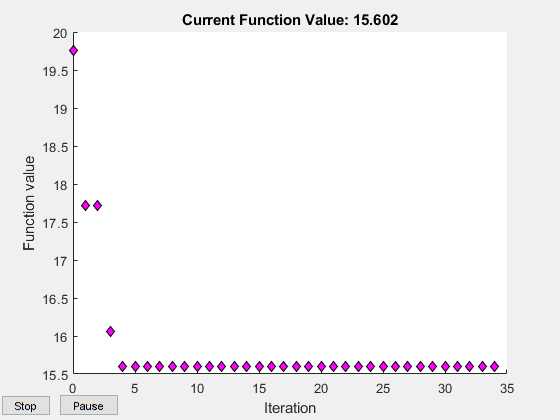


options = optimset('Tolx',0.0001,'Display','iter','PlotFcns',@optimplotfval);
U=[0.150 0.010] ;% initial values of the parameters you need to optimize.
F=@(U)calculateRMSE(Model, Medium, Geometry,U(1),U(2));
[U,fval,exitflag,output]=fminsearchbnd(F,U,[0.100 0.005],[0.250 0.02],options);



%options = optimoptions(@fminsearchbnd,'Display','iter','Algorithm','quasi-newton');



%visualization
figure(1)
plot(X_model, S_model_processed);
hold on
plot(X_exp, S_exp_processed);
hold on
%plot(X_exp,fitresult(X_exp));
title(['absorption coefficient (curve fitting)=', num2str(ABCOE_curvefit),'           absorption coefficient (minimizing RMSE)=', num2str(ABCOE_fminsearch)])
ylabel('PA signal');
xlabel('X [m]');
legend('PA forward model', 'experimental');